Практика 4. QPSK-модуляция

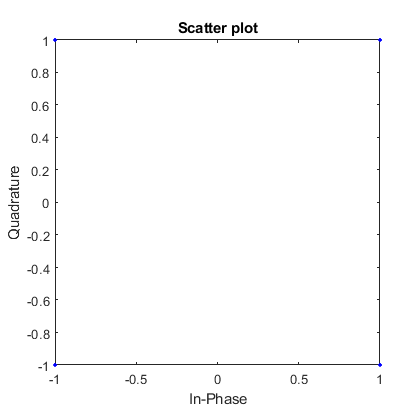

clear all;
[bitArray, alphabet, codedMessage] = znakCoding(3);

[convBitArray] = convCoder(bitArray);

[interleavingBits, interleavingPattern] = interleavingEncoder(convBitArray);

[qpskComplex] = qpskEncoder(interleavingBits);
scatterplot(qpskComplex); xlim([-1, 1]); ylim([-1, 1]);


[qpskBits] = qpskDecoder(qpskComplex);